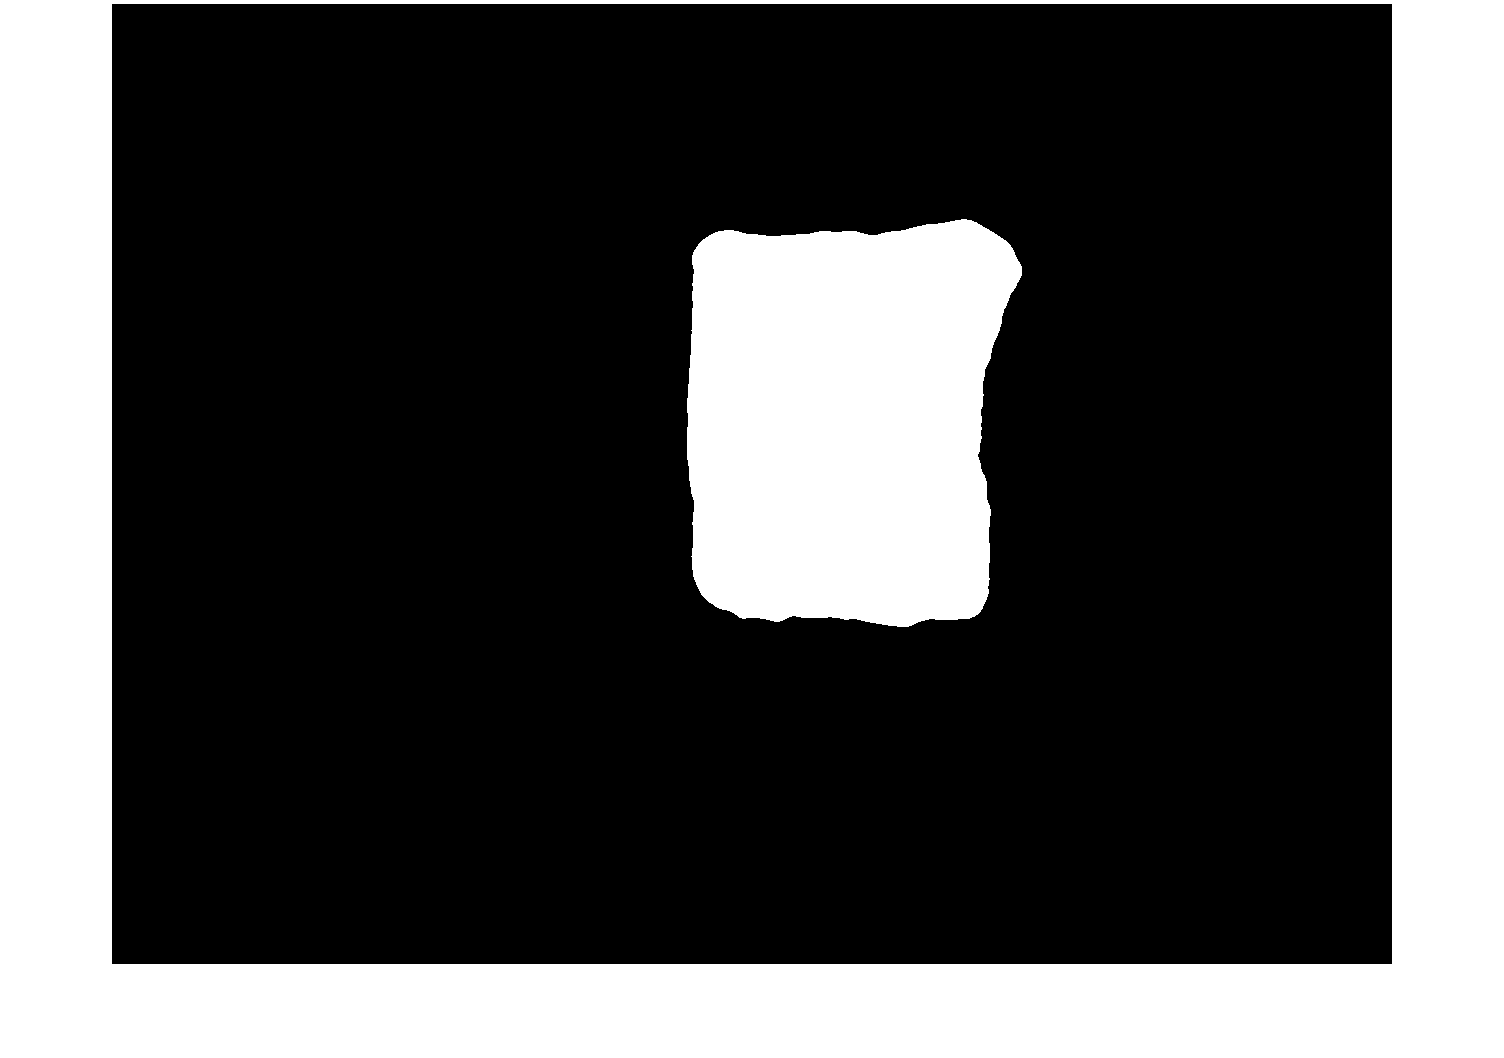

clear all
close all
clc


spoolSideCam = webcam('USB Camera #2');
spoolSide = snapshot(spoolSideCam);
FilimentMaskFunction = @OrangeFilimentMask;
spoolEmptySize = 306;
spoolFullSize = 800;
spoolFullWeight = 1;


spoolSideFiltered = FilimentMaskFunction(spoolSide);
spoolSideFiltered = medfilt2(spoolSideFiltered, [50, 50]);
imshow(spoolSideFiltered)

info = regionprops(spoolSideFiltered,'Area','BoundingBox');
boundBox = info(1).BoundingBox;
boundBox

boundBox =   575.5000  215.5000  335.0000  408.0000


pixSize = boundBox(4)

pixSize = 408

ratio = (pixSize^2 - spoolEmptySize^2) / (spoolFullSize^2 - spoolEmptySize^2);
weight = ratio * spoolFullWeight;

ratio

ratio = 0.1333